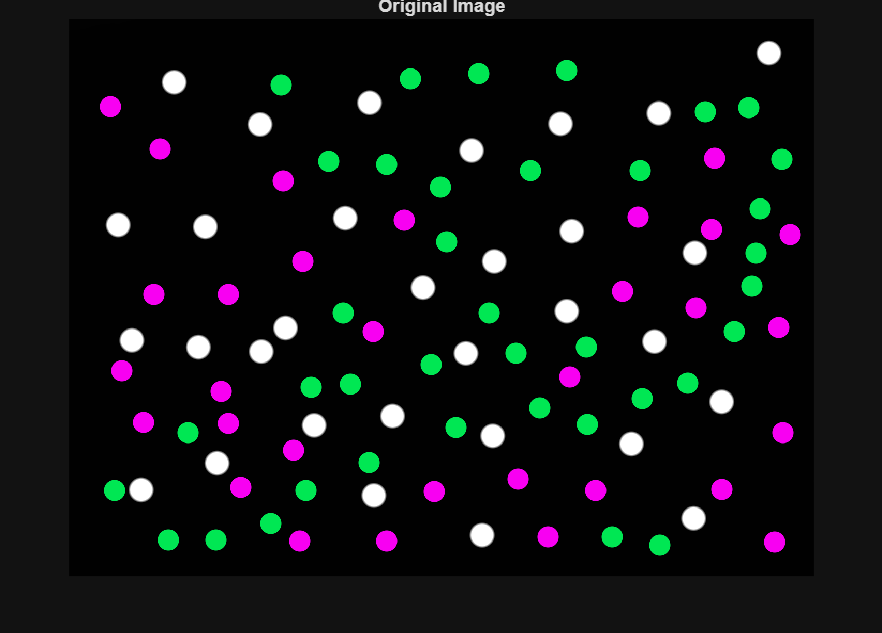

%% ========================================================================
%  PILL COUNTER - Image Processing Project
%  Counts the number of white pills in an image using:
%  Grayscale conversion -> Noise removal -> Filtering -> Thresholding ->
%  Morphological operations -> Connected component labeling -> Counting
% =========================================================================

clc;
clear;
close all;

%% 1. READ THE IMAGE
% Replace 'pills.jpg' with your own image file name/path
originalImage = imread('pills3.png');

figure('Name','Original Image');
imshow(originalImage);
title('Original Image');

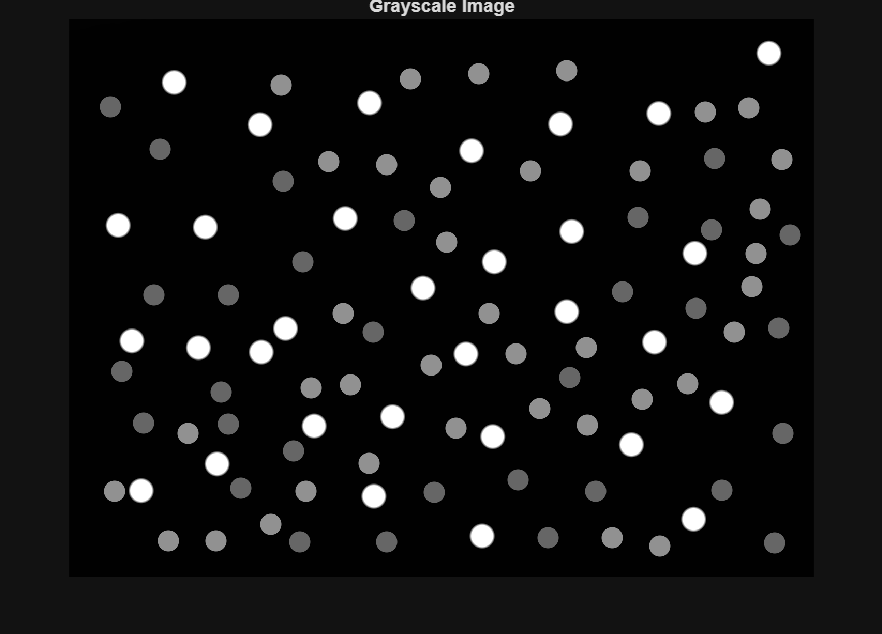


%% 2. CONVERT TO GRAYSCALE
% Color information is not needed for counting objects,
% so we convert RGB to grayscale to simplify processing.
if size(originalImage,3) == 3
    grayImage = rgb2gray(originalImage);
else
    grayImage = originalImage;
end

figure('Name','Grayscale Image');
imshow(grayImage);
title('Grayscale Image');

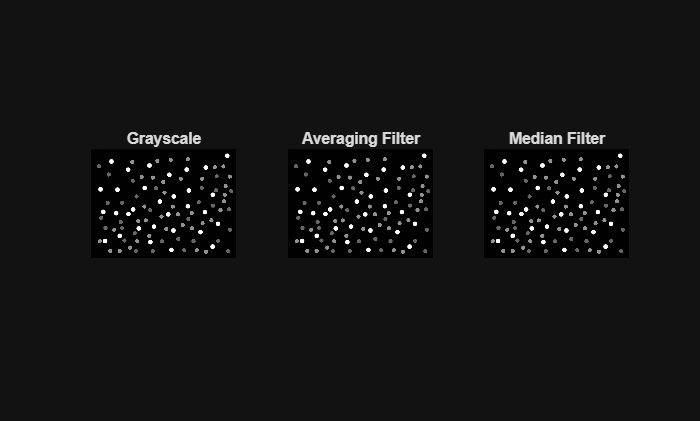


%% 3. NOISE REMOVAL (SMOOTHING / AVERAGING FILTER)
% A median filter is generally best for removing salt-and-pepper noise
% while preserving edges (better than averaging for this purpose).
% We also show an averaging filter as required by the project.

% --- Averaging (Mean) Filter ---
avgFilter = fspecial('average', [3 3]);   % 3x3 averaging kernel
avgFiltered = imfilter(grayImage, avgFilter);

% --- Median Filter (better noise removal, edge-preserving) ---
medianFiltered = medfilt2(grayImage, [3 3]);

figure('Name','Noise Removal');
subplot(1,3,1); imshow(grayImage);      title('Grayscale');
subplot(1,3,2); imshow(avgFiltered);    title('Averaging Filter');
subplot(1,3,3); imshow(medianFiltered); title('Median Filter');

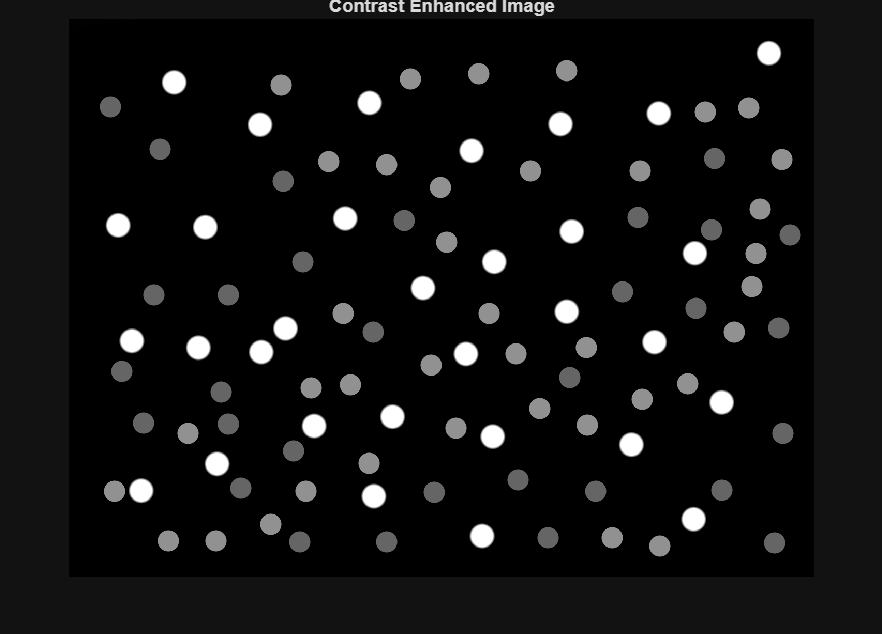


% We proceed with the median-filtered image (cleaner result)
filteredImage = medianFiltered;

%% 4. CONTRAST ENHANCEMENT (Optional but improves segmentation)
enhancedImage = imadjust(filteredImage);

figure('Name','Contrast Enhanced Image');
imshow(enhancedImage);
title('Contrast Enhanced Image');

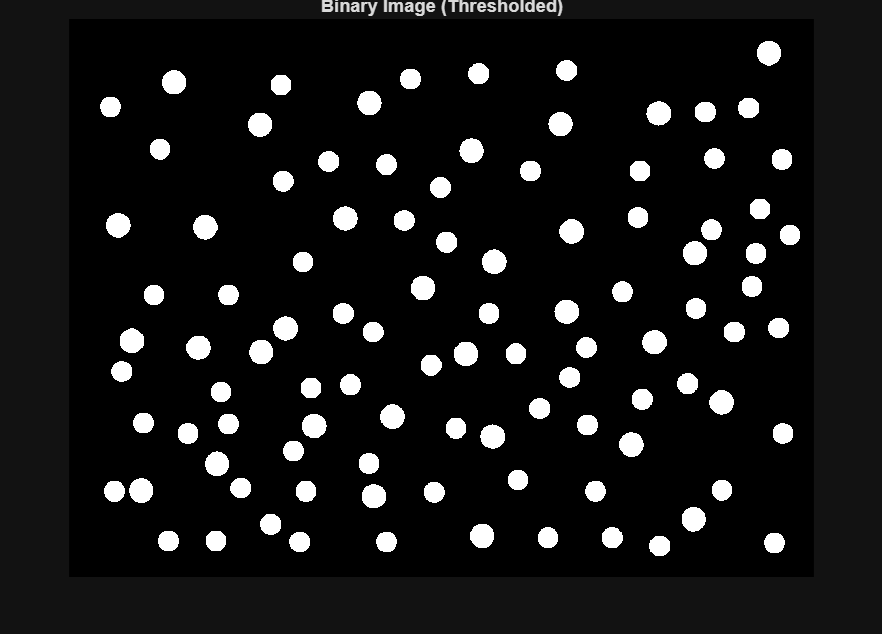


%% 5. THRESHOLDING (SEGMENTATION)
% Otsu's method automatically calculates the optimal global threshold
% to separate white pills (foreground) from the background.
level = graythresh(enhancedImage);         % Otsu threshold (0 to 1)
binaryImage = imbinarize(enhancedImage, level);

figure('Name','Binary Image (After Thresholding)');
imshow(binaryImage);
title('Binary Image (Thresholded)');

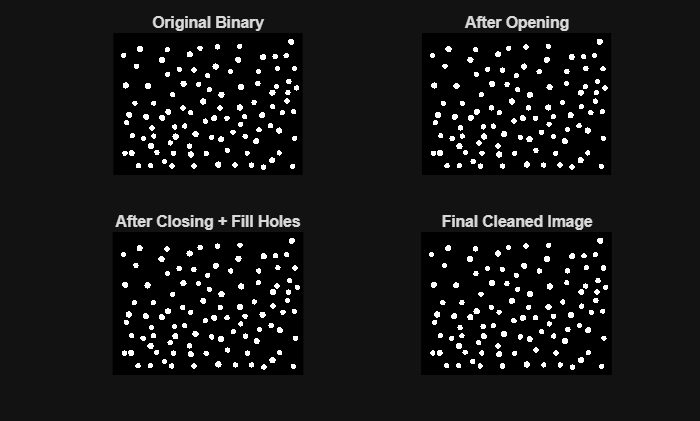


%% 6. MORPHOLOGICAL OPERATIONS (CLEAN-UP)
% Remove small noise particles and fill holes inside pills so each
% pill becomes one solid connected blob.

se = strel('disk', 3);                      % structuring element

% Opening removes small white noise specks
opened = imopen(binaryImage, se);

% Closing fills small black holes/gaps inside pills
closed = imclose(opened, se);

% Fill any remaining holes completely (e.g., reflections on pill surface)
filledImage = imfill(closed, 'holes');

% Remove very small objects (noise) below a certain pixel area
cleanedImage = bwareaopen(filledImage, 150); % adjust threshold as needed

figure('Name','Morphological Processing');
subplot(2,2,1); imshow(binaryImage);   title('Original Binary');
subplot(2,2,2); imshow(opened);        title('After Opening');
subplot(2,2,3); imshow(filledImage);   title('After Closing + Fill Holes');
subplot(2,2,4); imshow(cleanedImage);  title('Final Cleaned Image');

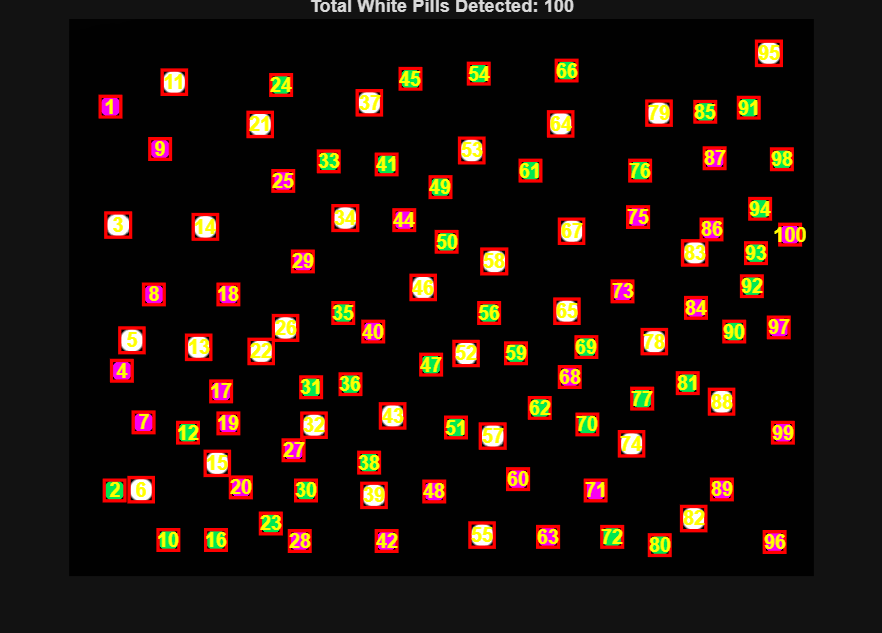


%% 7. CONNECTED COMPONENT LABELING & COUNTING
% Label each connected white blob (pill) as a separate object.
[labeledImage, numPills] = bwlabel(cleanedImage);

% Get properties of each labeled region
stats = regionprops(labeledImage, 'Centroid', 'Area', 'BoundingBox');

%% 8. DISPLAY FINAL RESULT WITH COUNT & LABELS
figure('Name','Final Result - Pill Count');
imshow(originalImage);
hold on;
title(['Total White Pills Detected: ', num2str(numPills)]);

for k = 1:numPills
    % Draw bounding box around each detected pill
    bb = stats(k).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);

    % Label each pill with a number at its centroid
    centroid = stats(k).Centroid;
    text(centroid(1), centroid(2), num2str(k), ...
        'Color', 'yellow', 'FontSize', 12, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
end
hold off;


%% 9. DISPLAY RESULT IN COMMAND WINDOW
fprintf('----------------------------------------\n');

----------------------------------------


fprintf('Total number of white pills detected: %d\n', numPills);

Total number of white pills detected: 100


fprintf('----------------------------------------\n');

----------------------------------------



% Optional: Display area of each pill (useful to detect broken/overlapping pills)
for k = 1:numPills
    fprintf('Pill %d -> Area: %d pixels\n', k, stats(k).Area);
end

Pill 1 -> Area: 1280 pixels
Pill 2 -> Area: 1304 pixels
Pill 3 -> Area: 1759 pixels
Pill 4 -> Area: 1280 pixels
Pill 5 -> Area: 1756 pixels
Pill 6 -> Area: 1756 pixels
Pill 7 -> Area: 1280 pixels
Pill 8 -> Area: 1280 pixels
Pill 9 -> Area: 1280 pixels
Pill 10 -> Area: 1304 pixels
Pill 11 -> Area: 1757 pixels
Pill 12 -> Area: 1304 pixels
Pill 13 -> Area: 1753 pixels
Pill 14 -> Area: 1758 pixels
Pill 15 -> Area: 1753 pixels
Pill 16 -> Area: 1304 pixels
Pill 17 -> Area: 1280 pixels
Pill 18 -> Area: 1280 pixels
Pill 19 -> Area: 1280 pixels
Pill 20 -> Area: 1280 pixels
Pill 21 -> Area: 1759 pixels
Pill 22 -> Area: 1758 pixels
Pill 23 -> Area: 1304 pixels
Pill 24 -> Area: 1304 pixels
Pill 25 -> Area: 1280 pixels
Pill 26 -> Area: 1757 pixels
Pill 27 -> Area: 1280 pixels
Pill 28 -> Area: 1280 pixels
Pill 29 -> Area: 1280 pixels
Pill 30 -> Area: 1304 pixels
Pill 31 -> Area: 1304 pixels
Pill 32 -> Area: 1753 pixels
Pill 33 -> Area: 1304 pixels
Pill 34 -> Area: 1765 pixels
Pill 35 -> Area: 1304 p